# EE4311 [2610] Lab 2: Mamdani Fuzzy PD Controller 3×3

## 1    Introduction

This lab is the same as lab 1, but this time, instead of a PD controller, we use a fuzzy logic PD controller to control the system. The controller is implemented as a Mamdani fuzzy inference system, and we use 3 terms each for the proportional error, derivative error, and output force to form our fuzzy rules.

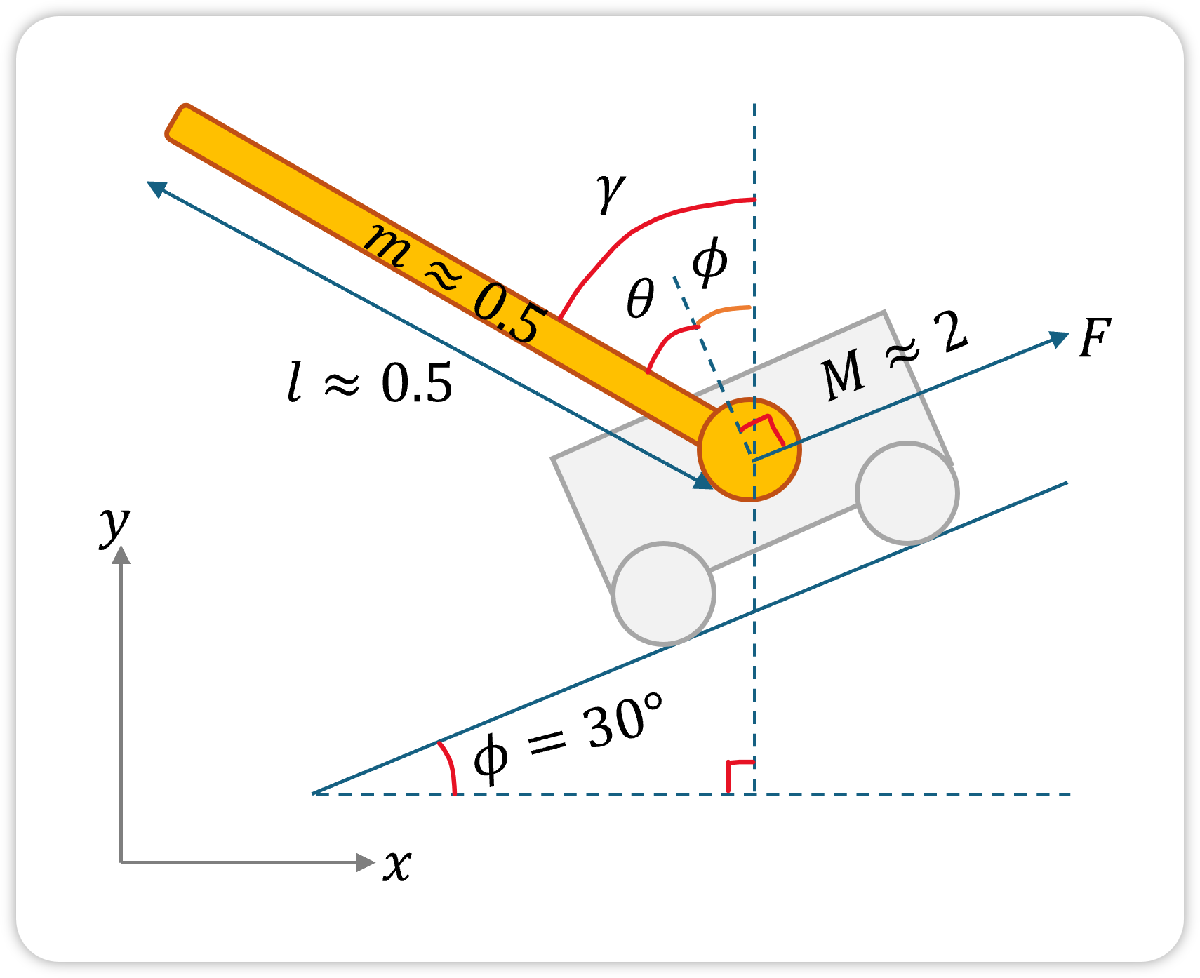

The worksheet is organized as follows:

- Section 2 requires you to define the random seed and tune parameters.

- Section 3 requires you to build the Mamdani fuzzy inference system.

- Section 4 requires you to define the controller to balance the pendulum.

- Section 5 simulates the system with the controller, and outputs the responses.

- Section 6 allows you to export and figures that are generated by the worksheet.

- Section 7 includes deadlines and submission requirements.

- Section 8 shows a preview of the questions to be answered on Canvas for this lab.

## 2    Definitions

In this section, we define tunable parameters and constants.

### 2.1    Initializations of Constants

- Replace the numbers with the numeric digits of your matric number. If your matric number is A0123456A, then the line should be `rng(123456)`.

clear all; close all; clc; format compact
rng(284748); % !TODO (1)
 
constants = struct();
constants.G = 9.8;
constants.M_CART = rand() * 1 + 1.5; % cart mass, kg
constants.M_PEND = rand() * 0.2 + 0.4; % pend mass, kg
constants.L_PEND = rand() * 0.2 + 0.4; % pend length, m
constants.PHI = 30; % slope angle, deg
constants.GAMMA_SET = 1; % settling angle, deg
constants.START_GAMMAS = [-10, -5, 5, 10]; % deg
constants.F_UNI = [-inf, inf];
constants.D_UNI = [-inf, inf];
constants.P_UNI = [-inf, inf];

fprintf("Slope=%.3f deg; Cart mass=%.3f kg; Pend mass=%.3f kg; Pend length=%.3f m\n", constants.PHI, constants.M_CART, constants.M_PEND, constants.L_PEND);

Slope=30.000 deg; Cart mass=1.574 kg; Pend mass=0.517 kg; Pend length=0.474 m


### 2.2    Find Weight Along Slope

Find the magnitude of the force pointing down the slope that is contributed by the weight of the system. This force is parallel to and pointing down the slope, and may be useful for tuning. Let this be stored in the `constants.WEIGHT`. To calculate the force, the following constants may be used:

- `constants.G`: Acceleration due to gravity, in m/s/s.

- `constants.PHI`: the slope angle, in ***degrees***.

- `constants.M_CART`: the mass of the cart, in kg

- `constants.M_PEND`: the mass of the pendulum, in kg.

constants.WEIGHT = (constants.M_CART + constants.M_PEND)*(constants.G)*(sind(constants.PHI)); % !TODO
fprintf("Cart Weight=%.3f kg  \n", constants.WEIGHT);

Cart Weight=10.244 kg  


### 2.3    Universes of Discourse

Suppose the universe of discourse defined to between a value $a$ and another value $b$ inclusive, and $a<b$, and the definition has to be stored in `constants.I_UNI`. Then, the code is `constants.I_UNI = [a, b];` where `[a, b]` is an array in MATLAB.

Using the example, define the universe of discourse for...

- the proportional error, which is between -40 and 40 (deg) inclusive, to be stored in `constants.P_UNI`.

- the derivative error, which is between -80 and 80 (deg/s) inclusive, to be stored in `constants.D_UNI`.

- the output force, which is between -70 and 70 (N) inclusive, to be stored in `constants.F_UNI`. The system can only output a maximum of 50 N. The extra 20 N is meant for redundancy, and you will need to examine the calculations in the fuzzy system to understand why this is desirable.

Ignore the units when assigning the arrays.

% !TODO (1)
constants.P_UNI = [-40 , 40]

constants = struct with fields:
               G: 9.8000
          M_CART: 1.5736
          M_PEND: 0.5170
          L_PEND: 0.4741
             PHI: 30
       GAMMA_SET: 1
    START_GAMMAS: [-10 -5 5 10]
           F_UNI: [-Inf Inf]
           D_UNI: [-Inf Inf]
           P_UNI: [-40 40]
          WEIGHT: 10.2441

% !TODO (2)
constants.D_UNI = [-80 , 80]

constants = struct with fields:
               G: 9.8000
          M_CART: 1.5736
          M_PEND: 0.5170
          L_PEND: 0.4741
             PHI: 30
       GAMMA_SET: 1
    START_GAMMAS: [-10 -5 5 10]
           F_UNI: [-Inf Inf]
           D_UNI: [-80 80]
           P_UNI: [-40 40]
          WEIGHT: 10.2441

% !TODO (3)
constants.F_UNI = [-70 , 70]

constants = struct with fields:
               G: 9.8000
          M_CART: 1.5736
          M_PEND: 0.5170
          L_PEND: 0.4741
             PHI: 30
       GAMMA_SET: 1
    START_GAMMAS: [-10 -5 5 10]
           F_UNI: [-70 70]
           D_UNI: [-80 80]
           P_UNI: [-40 40]
          WEIGHT: 10.2441

### 2.4    Membership Functions

The membership functions (MFs) are defined to be trapezoids, and are controlled by the parameters $a$, $b$, $c$, and $d$. 

1. For the input variable *proportional error*, there are three terms negative (N), near-zero (Z), and positive (P). Each term is described by a trapezoidal MF. The proportional error is in (deg).

- Define `params.P_N`, which is the trapezoidal MF for the proportional error's negative term. If $a=-10$, $b=-5$, $c=-5$, and $d=0$, define `params.P_N` as `[-10, -5, -5, 0]`.  The example code is shown below.

- Define `params.P_Z`, which is the trapezoidal MF for the proportional error's near-zero term.

- Define `params.P_P`, which is the trapezoidal MF for the proportional error's positive term.

2. For the input variable *derivative error*, do the same. The derivative error is in (deg/s).

- Define `params.D_N`, which is the derivative error's negative term.

- Define `params.D_Z`, which is the derivative error's near-zero term.

- Define `params.D_P`, which is the derivative error's positive term.

3. For the output variable *output force*, do the same. The output force is in (N).

- Define `params.F_N`, which is the output force's negative term.

- Define `params.F_Z`, which is the output force's near-zero term.

- Define `params.F_P`, which is the output force's positive term.

% parameters for all trapmf 
params = struct();
node_p = 4;
node_d = 40;
node_f = 30;
% !TODO (1)
params.P_N = [-40, -40, -node_p, 0];
params.P_Z = [-node_p, 0, 0, node_p];
params.P_P = [0, node_p, 40, 40];
% !TODO (2)
params.D_N = [-80, -80, -node_d, 0];
params.D_Z = [-node_d, 0, 0, node_d];
params.D_P = [0, node_d, 80, 80];
% !TODO (3)
params.F_N = [-50, -50, -node_f, 0];
params.F_Z = [-node_f, 0, 0, node_f];
params.F_P = [0, node_f, 50, 50];

## 3    The Fuzzy Inference System

With the parameters and constants defined, we will now build the fuzzy inference system (FIS). `fis` is the variable holding the fis object, and is initialized as a Mamdani System using `mamfis()`. The documentation for various functions mentioned below can be found online. Note that all code in this subsection belong to our own custom function `initFis()`.

### 3.1    Input and Output Variables

The fuzzy system `fis` is first designed by adding input variables and output variables.

- Using `addInput()`, and `constants.P_UNI`, add an *input* variable to `fis` with the name `p` for the proportional error.

- Using `addInput()`, and `constants.D_UNI`, add an *input* variable to `fis` with the name `d` for the derivative error. 

- Using `addOutput()`, and `constants.F_UNI`, add an *output* variable to `fis` with the name `f` for the force.

function fis = initFis(constants, params)
fis = mamfis('Name', 'l2');

% !TODO(1)
fis = addInput(fis, constants.P_UNI, 'Name', 'p');
% !TODO(2)
fis = addInput(fis, constants.D_UNI, 'Name', 'd');
% !TODO(3)
fis = addOutput(fis, constants.F_UNI, 'Name', 'f');

### 3.2    Attach Membership Functions to Variables

The MFs for the input variables `p` and `d`, and the output variable `f` in `params` were defined earlier. Now, register the MFs into the model.

- Using `addMf()` multiple times, add the MFs for the term `p`.

- Do the same for `d`.

- Do the same for `f`.

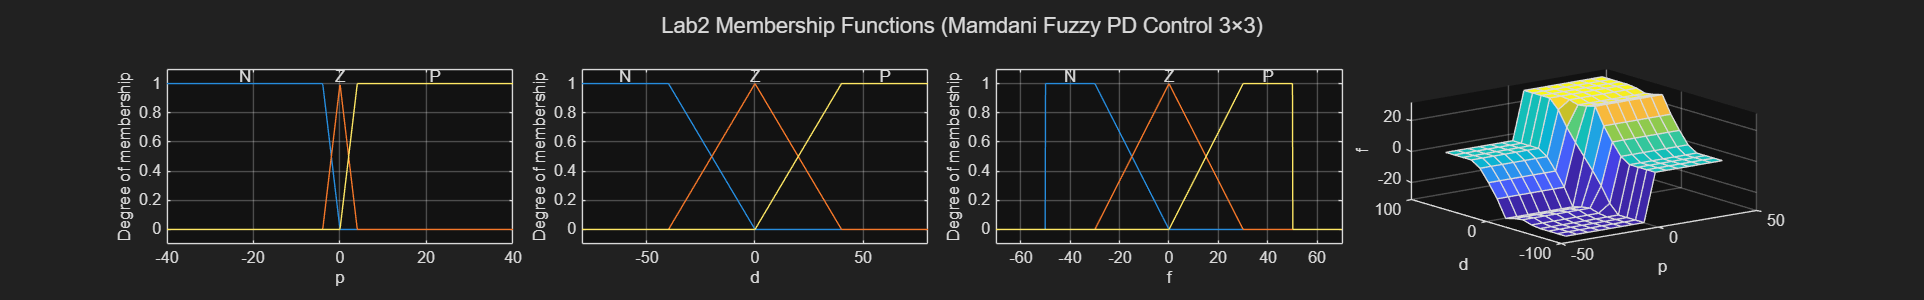

% !TODO (1)
fis = addMF(fis, 'p', 'trapmf', params.P_N, Name='N');
fis = addMF(fis, 'p', 'trapmf', params.P_Z, Name='Z');

fis = addMF(fis, 'p', 'trapmf', params.P_P, Name='P');
% !TODO (2)
fis = addMF(fis, 'd', 'trapmf', params.D_N, Name='N');
fis = addMF(fis, 'd', 'trapmf', params.D_Z, Name='Z');
fis = addMF(fis, 'd', 'trapmf', params.D_P, Name='P');
% !TODO (3)
fis = addMF(fis, 'f', 'trapmf', params.F_N, Name='N');
fis = addMF(fis, 'f', 'trapmf', params.F_Z, Name='Z');
fis = addMF(fis, 'f', 'trapmf', params.F_P, Name='P');

### 3.3    Apply Fuzzy Rules to Variables

Suppose `p`, `d`, and `f` have 3 terms each (N, Z, P). The $3\times 3$ rule table may be:

where each row corresponds to a term in `p` and each column corresponds to a term in `'d'`. One of the rules (row 3, col. 1) is:

if    `p` is `P`    and    `d` is `Z`     then   `f` is `N`

which will correspond to the following code:

`fis = addRule(fis, 'p==P & d==Z => f==N');`

Note that `P`, `Z`, `N` must correspond to the label used to `Name` argument when the MFs are attached to the variables. If the labels are different, the code will throw an error.

- Program the $3\times3$ rules using `addRule()`. To minimize semantic errors, make use of the comments to tabulate the rules.

% You may use the following comment block to tabulate the rules,
% so that it is easier to code the rules.
%       d=N    d=Z    d=P
% p=N    Z      P      N
% p=Z    N      Z      P
% p=P    P      N      Z

% !TODO (1)

fis = addRule(fis, 'p==N & d==N => f==N');
fis = addRule(fis, 'p==N & d==Z => f==N');
fis = addRule(fis, 'p==N & d==P => f==Z');
fis = addRule(fis, 'p==Z & d==N => f==N');
fis = addRule(fis, 'p==Z & d==Z => f==Z');
fis = addRule(fis, 'p==Z & d==P => f==P');
fis = addRule(fis, 'p==P & d==N => f==Z');
fis = addRule(fis, 'p==P & d==Z => f==P');
fis = addRule(fis, 'p==P & d==P => f==P');



% Proportional Only Rules:
% fis = addRule(fis, 'p==N => f==N');
% fis = addRule(fis, 'p==Z => f==Z');
% fis = addRule(fis, 'p==P => f==P');

### 3.4    Fuzzy Methods

To make sure the Mamdani fuzzy inference system is used, make sure that the following methods are defined the same as in the lecture:

- `AndMethod`, for implementing the *and* condition in the antecedent.

- `OrMethod`, for implementing the *or* condition in the antecedent.

- `ImplicationMethod`, for the implication step, or the shape of the consequent MF from the firing strength for each rule.

- `AggregationMethod`, for the aggregation step, which is to combine all of the consequent MFs from all rules.

- `DefuzzificationMethod`, which is to find the defuzzified crisp value from the aggregated MF.

Refer the online documentations to do the tutorials.

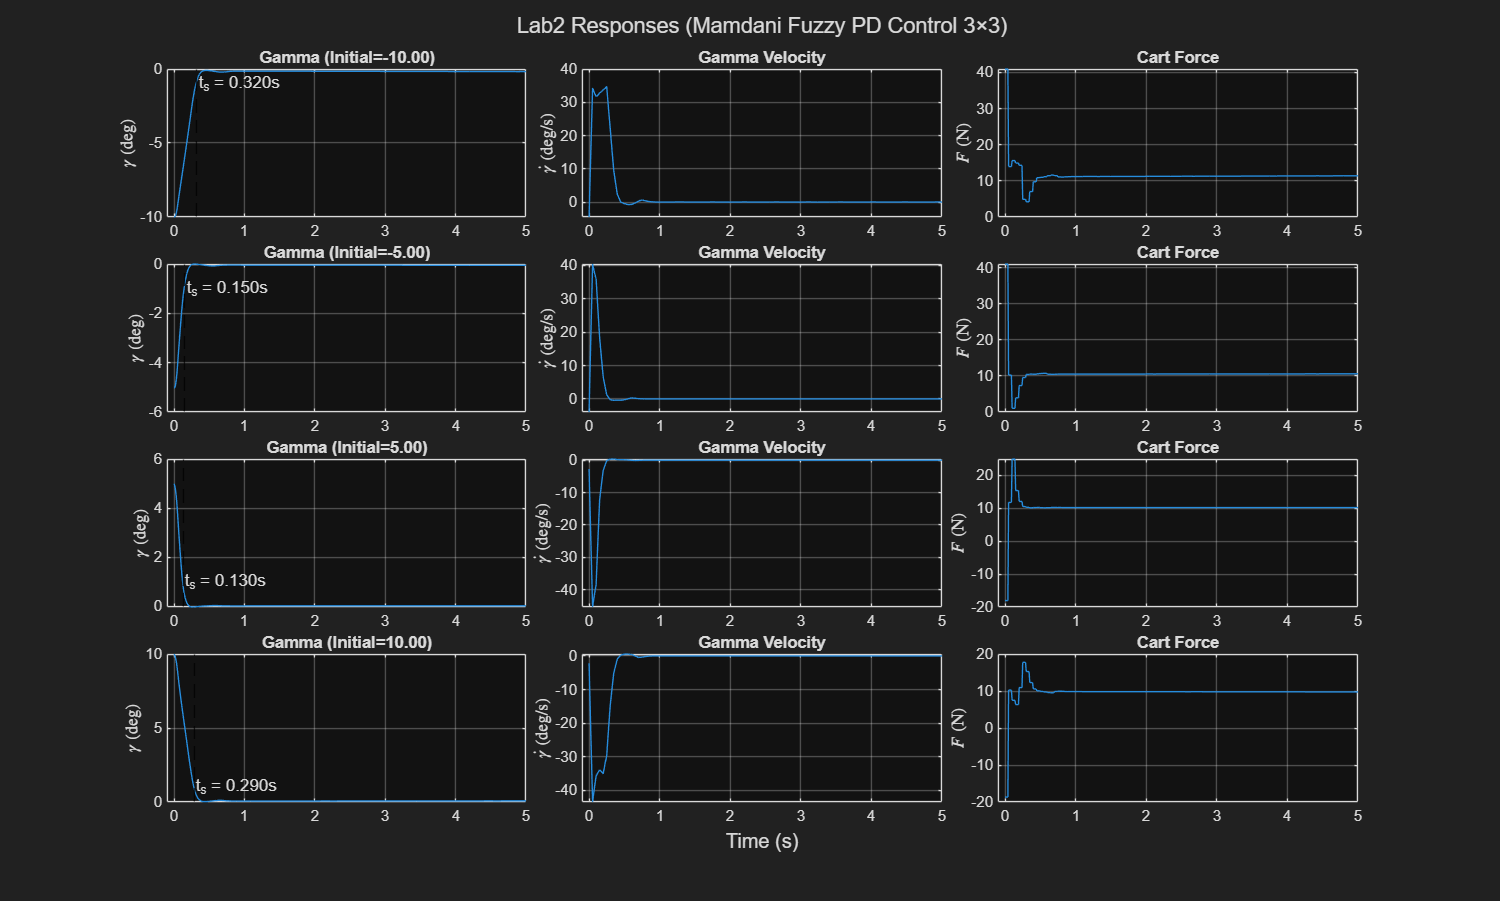

% !TODO (1)
fis.AndMethod = 'min';


% !TODO (2)
fis.OrMethod = 'max';

% !TODO (3)
fis.ImplicationMethod = 'min';

% !TODO (4)

Saving images to C:\Users\adity


fis.AggregationMethod = 'max';

% !TODO (5)
fis.DefuzzificationMethod = 'centroid';

end %function end

### 3.5    Plot Membership Functions and Output Surface

Run the code in section 2 using `Ctrl+Enter`. Fix any errors that show up.

fis = initFis(constants, params); % call the function

% plot the MFs
function fig1 = plotFuzzyInferenceSystem(fis)
fig1 = figure(1);
tld = tiledlayout(1, 4, 'TileSpacing', 'Tight');
title(tld, "Lab2 Membership Functions (Mamdani Fuzzy PD Control 3×3)");
fig1.Position = [20, 20, 1600, 240];

nexttile;
plotmf(fis, 'input', 1, 1000);
grid on;

nexttile;
plotmf(fis, 'input', 2, 1000);
grid on;

nexttile;
plotmf(fis, 'output', 1, 1000);
grid on;

nexttile;
gensurf(fis);
grid on;
end

fig1 = plotFuzzyInferenceSystem(fis);
set(fig1, 'Visible', 'on')

## 4    Controller

The angle $\gamma$ (deg) and its velocity $\dot{\gamma}$ (deg/s) are stored in `gamma` and `gamma_vel` respectively. In the function `controller()`, implement the controller using the fuzzy inference system `fis` to output a force `f` to move the cart. 

- Calculate the proportional error `p`. It is the desired angle subtracted by the current angle `gamma`.

- Calculate the derivative error `d`. It is the desired angular velocity subtracted by the current angular velocity `gamma_vel`.

- Using `evalfis()`, calculate the force `f` that is output by the fuzzy inference system `fis` using the inputs `p` and `d`.

function f = controller(fis,constants, gamma, gamma_vel)
% !TODO (1)
p = 0 - gamma;
% !TODO (2)
d = 0 - gamma_vel;
% !TODO (3)

f = evalfis(fis , [p ,d]) + constants.WEIGHT;

end

## 5    Simulation

By tuning the membership functions and rules, ensure that the following requirements are met (same as lab 1):

- The settling time for $1\degree$ must be 0.5s or less for all starting angles $\gamma_0 \in\{-10, -5, 5, 10\}$. The settling time can be seen in the figure as $t_s$.

- Overshoot in $\gamma$ is less than $1\degree$.

- Steady state $\gamma$ should be as close to zero as possible. Hint: you may need to add something in the `controller` function.

- Negligible oscillations in all responses.

- Ignore the cart's displacement and velocity.

The following tuning process is suggested:

- Set the slope angle to 0 in the first code block (`constants.PHI = 0`, at the first code block). This is to balance the force on the pendulum and make it easier to tune.

- Initialize and distribute the MFs in `p`. (i) For `N`, define `a` and `b` to be at the negative edge of the universe and `d` to be at zero. (ii) For `P`, define `c` and `d` to be at the positive edge of the universe and `a` to be at zero. (iii) For `Z`, make it a triangle by equating `b` and `c` at zero, and `a` equals to the `c` of `N`, and `d` equals to the `b` of P. (iv) By equating the parameters, realize that only **two nodes** has to be adjusted. The **first node** is the `c` of `N` and `a` of `Z`, and the **second node** is the `b` of `P` and `d` of `Z`. Put the nodes halfway between the edge of the universe and zero.

- Do the same for MFs in `f`, but the extreme left and right parameters should be at -50 and 50 instead of -70 and 70.

- Modify the rules in Section 3.3 so that the force is due only to the proportional error.

- Begin compressing the two nodes in `p` symmetrically towards zero, while keeping the other values unchanged. Observe what happens to the gamma responses, and relate these observations to that in lab 1 when `p` is adjusted. Continue tuning until the response in gamma steadily oscillates around the setpoint $\gamma = 0$.

- The system will output no force if the proportional error exceeds the universe, and the pendulum oscillates around $180\degree$. When this occurs, check if the gamma crosses zero. If it does, too much force is used. If it does not, too little force is used. Change the MFs in `p` or `f` accordingly.

- Once the responses are oscillating steadily about the setpoint, re-modify the rules in Section 3.3 to include the derivative error `d`.

- Initialize and distribute the MFs in d the same way as it is done for p and f.

- Begin compressing the two nodes in d symmetrically towards zero, while keeping the other values unchanged. Again, observe what happens and relate the observations back to lab 1.

- Tune the MFs until the steady state error is zero..

- Now, **put the slope angle back to **$30\degree$ (`constants.PHI = 30`), and re-tune the system until the steady state error is zero.

**Just run. Ignore the code in this section.** The code uses Euler Lagrange formulation to simulate the system.

function response = simulate(fis, constants, start_gamma)

% start_gamma is in degrees.
DT = 0.01; % simulate frequency in seconds.
DT2 = DT * DT;
T_TOTAL = 5; % in seconds
CTRL_STEP = 5; % 5*DT is controller frequency.
KF_CART = 3; % cart friction coeff
KF_PEND = 1e-4; % pend friction coeff
S_PHI = sind(constants.PHI);
C_PHI = cosd(constants.PHI);
M_TOTAL = constants.M_CART + constants.M_PEND;
L76 = -constants.L_PEND * 7.0 / 6.0;
MML76 = M_TOTAL * L76;
WEIGHT = constants.G * S_PHI * M_TOTAL;

T = 0:DT:T_TOTAL; %sim for 0.01s for 10s
PS = nan(size(T)); % gamma
PV = nan(size(T));
F = nan(size(T));
f = 0;
theta = deg2rad(start_gamma - constants.PHI);
pv = 0;
cs = 0;
cv = 0;
for i = 1:numel(T)
    C_THETA = cos(theta);
    S_THETA = sin(theta);
    % From euler lagrange formulation
    tmp_a = f - 0.5*pv*pv*S_THETA - WEIGHT - cv*KF_CART;
    tmp_b = -constants.G * (S_THETA*C_PHI + C_THETA*S_PHI) - pv*KF_PEND;
    tmp_denom = MML76 - 0.5*C_THETA*C_THETA;
    ca = (L76*tmp_a + 0.5*C_THETA*tmp_b) / tmp_denom;
    pa = (-C_THETA*tmp_a + M_TOTAL*tmp_b) / tmp_denom;
    % linear approximation
    theta = theta + pv*DT + 0.5*pa*DT2;
    ps = theta + deg2rad(constants.PHI);
    pv = pv + pa*DT;
    cs = cs + cv*DT + 0.5*ca*DT2;
    cv = cv + ca*DT;
    % controller
    if mod(i-1, CTRL_STEP) == 0
        % ps = ps + randn()*1e-4; % corrupt with noise
        % pv = pv + randn()*1e-4; % corrupt with noise
        % controller
        f = controller(fis,constants, rad2deg(wrapToPi(ps)), rad2deg(pv));
        % saturate force like real world system
        f = clip(f, -50, 50);
    end
    PS(i) = ps;
    PV(i) = pv;
    F(i) = f;
end

response.gamma = rad2deg(wrapToPi(PS));
response.gamma_vel = rad2deg(PV);
response.force = F;
response.time = T;
end

% ================= function to analyze / evaluate response
function  response = evalResponse(response, constants)
    idx = find(flip(response.gamma < -constants.GAMMA_SET | response.gamma > constants.GAMMA_SET), 1, "first"); % flip the ps, find the first index when the response is outside of settling gamma. 
    if ~isempty(idx) && idx > 1 % has settling time. 
        response.settling_time = response.time(numel(response.gamma) - idx + 2);
    else
        response.settling_time = inf;
    end
end

% ================= run the simulation for all START_GAMMAS
responses = [];
for i = 1:numel(constants.START_GAMMAS)
    r = simulate(fis, constants, constants.START_GAMMAS(i));
    r = evalResponse(r, constants);
    responses = [responses, r];
end

% ===================== plot
function fig2 = plotResponses(responses, constants)
fig2 = figure(2);
fig2.Position = [0, 0, 1200, 720];
tld = tiledlayout(numel(constants.START_GAMMAS), 3, TileSpacing="tight");
title(tld, "Lab2 Responses (Mamdani Fuzzy PD Control 3×3)");
xlabel(tld, "Time (s)");
for i = 1:numel(constants.START_GAMMAS)
    r = responses(i);

    nexttile
    plot(r.time, r.gamma)
    start_gamma = constants.START_GAMMAS(i);
    title(sprintf('Gamma (Initial=%.2f)', start_gamma));
    if (~isinf(r.settling_time))
        xline(r.settling_time, '--k');
        text(r.settling_time, sign(start_gamma) * constants.GAMMA_SET, sprintf('t_s = %.3fs', r.settling_time))
    end
    grid on
    xlim([-0.1, r.time(end)])
    ylabel("$\gamma$ (deg)", Interpreter="latex");

    nexttile
    plot(r.time, r.gamma_vel)
    title('Gamma Velocity');
    grid on
    xlim([-0.1, r.time(end)])
    ylabel("$\dot{\gamma}$ (deg/s)", Interpreter="latex");

    nexttile
    plot(r.time, r.force)
    title('Cart Force');
    grid on
    xlim([-0.1, r.time(end)])
    ylabel("$F$ (N)", Interpreter="latex");
end
end

fig2 = plotResponses(responses, constants);
set(fig2, 'Visible', 'on');

## 6    Export Figures

You can save the figures into images (`.png`) by running the code below. The images will be saved in the current folder.

% exportgraphics(fig1,'l2_parameters.pdf','BackgroundColor','none','ContentType','vector');
% exportgraphics(fig2,'l2_responses.pdf','BackgroundColor','none','ContentType','vector');

fprintf("Saving images to %s\n", pwd());
exportgraphics(fig1,'l2_parameters.png','BackgroundColor','white');
exportgraphics(fig2,'l2_responses.png','BackgroundColor','white');

## 7    Administrative Requirements

- **Individual Work**, 100 marks in total, 10% of total grade.

- **Deadline W6 Sun (20 Sep) 23:59h**. See Canvas for most recent deadline.

### 7.1    Submit MLX Worksheet

- **Submit .mlx Worksheet** to `Canvas` ▶ `Assignments` ▶ `L2`:

- (5 marks) Rename the file as `l2_a########.mlx` in ***lowercase***, where `a#########` is your matric number (e.g. `l2_a0123456a.mlx`).

- (5 marks) **Your name should not appear** in the worksheet, only the matric number.

- (5 marks) Overshoot in gamma is less than $1\degree$ on the $30\degree$ slope.

- (5 marks) Settling time is less than 0.5s for all responses on the $30\degree$ slope.

- (5 marks) Zero steady state error for all responses on the $30\degree$ slope.

- (25 marks) will be based on your fuzzy system code.

- **No errors while running** to ensure that marks can be given. Some code will be copied to a solution template for testing, so change only the code as requested and do not modify the rest.

### 7.2    Answer Questions on Canvas

- **Answer written questions** in the next section on `Canvas` ▶ `Assignments` ▶ `L2Q`.

## 8    Questions

Answer the questions on L2Q on Canvas. Included here for convenience.

### 8.1    Tuning MFs for Proportional Error

(10 marks) In the suggested tuning process, two nodes of the `p` membership functions are mentioned. When these two nodes are moved closer to zero, is this analogous to increasing or decreasing the proportional gain? Explain why.

### 8.2    Tuning MFs for Derivative Error

(10 marks) When the two nodes of `d`'s membership function are moved closer to zero, is this analogous to increasing or decreasing the derivative gain? Explain why.

### 8.3    Tuning MFs for Output Force

(10 marks) When the two nodes of `f`'s membership function are moved closer to zero, does this increase or decrease the output force when either `N` or `P` for `f` is fired by the rules? Explain why.

### 8.4    Non-overlapping Membership Functions

(10 marks) Consider the initial tuning process when the slope is $0\degree$, and the output force is dependent only on the proportional error but not the derivative error (i.e. only P control). Suppose the supports of `N` and `P` are far apart from each other but still overlapping with the support of the `Z` membership function as shown in the image below. What might be a problem with the control, assuming that the pendulum is able to stay near $\gamma=0$ and the force membership functions are reasonably defined? Explain why.

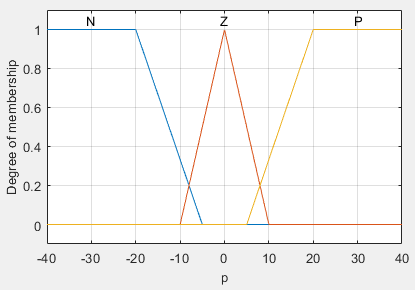

### 8.5    Redundancy in Output Force's Universe of Discourse

(10 marks) The maximum force that can be applied to the cart is 50 N in either direction. Why is it desirable for the universe of discourse for `f` to be between -70 and 70, especially if the slope angle is large?